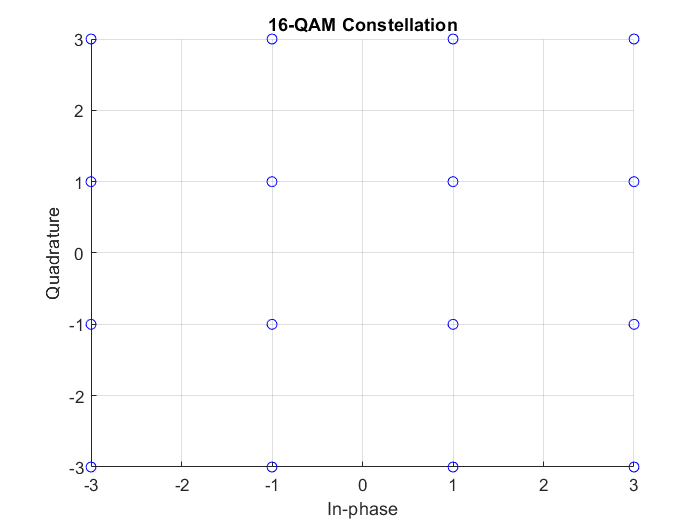

%generate QAM modulation and obtain its consellation 
M=16;
N= 1000;
bits=randi([0 1],1,N);
symbols=zeros(1,N/4);
for i=1:N/4
symbols(i) = (2*bits(4*i-3)-1)+1j*(2*bits(4*i-2)-1)+2*(2*bits(4*i-1)-1)+2j*(2*bits(4*i)-1);
end
scatter(real(symbols),imag(symbols),'bo');
grid on;
xlabel('In-phase'); ylabel('Quadrature');
title('16-QAM Constellation');

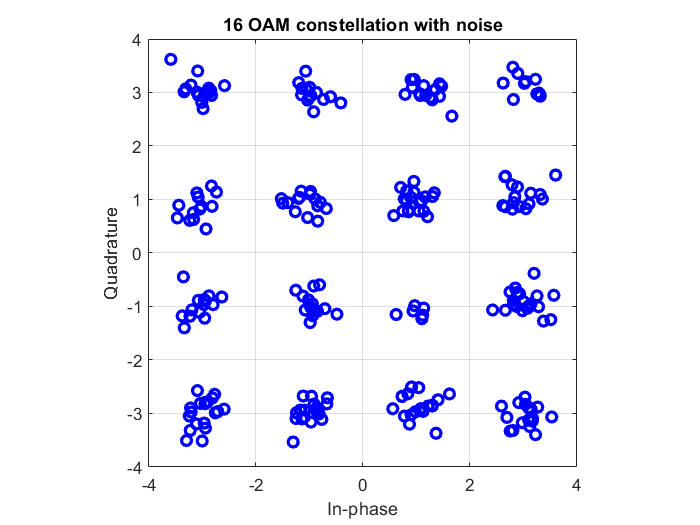

%simulate AWGN CHANNEL
snr_db=20;
rx_signal=awgn(symbols,snr_db,'measured');
figure;
plot(real(rx_signal),imag(rx_signal),'bo','Markersize',6,'Linewidth', 2)
xlabel('In-phase');
ylabel('Quadrature');
title('16 OAM constellation with noise')
grid on;
axis equal;
axis([-4 4 -4 4]);